# Calculate Features

Instructions are in the task pane to the left. Complete and submit each task one at a time.

Do not edit. This code loads and preprocesses the data.

clear;clc
letter = readtable("user001_M_1.txt");
letter.X = letter.X*1.5;
letter.Time = (letter.Time - letter.Time(1))/1000

letter = 28×4 table
    Time       X         Y        P  
    _____    ______    _____    _____

        0    1.1625    0.228    0.042
    0.002    1.1625    0.227    0.255
    0.002    1.1625    0.227    0.255
    0.019     1.161    0.221     0.44
    0.027     1.161    0.214    0.569
    0.044    1.1595    0.199    0.745
     0.06     1.158    0.188      0.8
     0.08     1.158    0.176    0.851
    0.094    1.1595    0.173     0.88
    0.138    1.1655    0.194    0.894
    0.143     1.167    0.201    0.896
    0.169     1.176    0.228    0.899
    0.189    1.1835    0.249    0.923
    0.194     1.185    0.251    0.931
    0.212    1.1865    0.248    0.995
    0.252     1.185    0.209        1


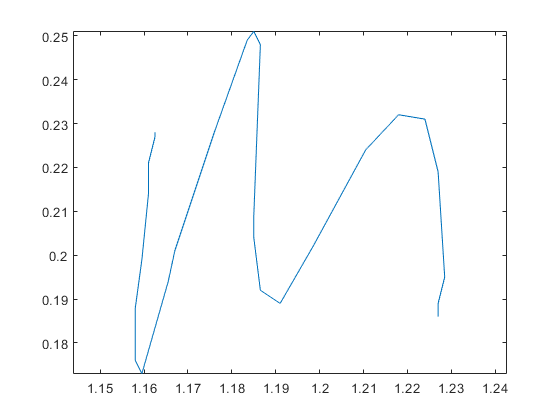

plot(letter.X,letter.Y)
axis equal

## Task 1

Calculate the time taken to write the letter by extracting the last value of `letter.Time` and storing the result in a variable called `dur`.

dur = letter.Time(end)

dur = 0.4560

## Task 2

Use the `range` function to calculate the aspect ratio(長寬比) of the letter by dividing the range of values of `letter.Y` by the range of values of `letter.X`. Assign the result to a variable called `aratio`.

aratio = range(letter.Y)/range(letter.X)

aratio = 1.1064

## Further Practice

Change the file name and rerun the script to calculate the same two features for the letters in `J.txt` and `V.txt`. Are the values of the features consistent with what you'd expect for these letters?

letter2 = readtable("user001_J_1.txt");
letter2.X = letter2.X*1.5;
letter2.Time = (letter2.Time - letter2.Time(1))/1000

letter2 = 28×4 table
    Time       X         Y        P  
    _____    ______    _____    _____

        0     0.561    0.239     0.04
    0.012     0.561    0.241     0.22
    0.012     0.561    0.241     0.22
    0.027     0.561    0.244    0.376
    0.049     0.561    0.245     0.55
    0.062     0.561    0.244    0.608
    0.079    0.5625    0.239    0.729
    0.094    0.5625    0.228    0.792
    0.111     0.564    0.212    0.853
    0.112     0.564    0.208    0.862
    0.129     0.564    0.189    0.909
    0.145     0.561    0.169    0.989
     0.16     0.558    0.155        1
    0.177     0.549    0.142        1
    0.194    0.5415    0.138    0.985
    0.212    0.5325    0.141    0.524


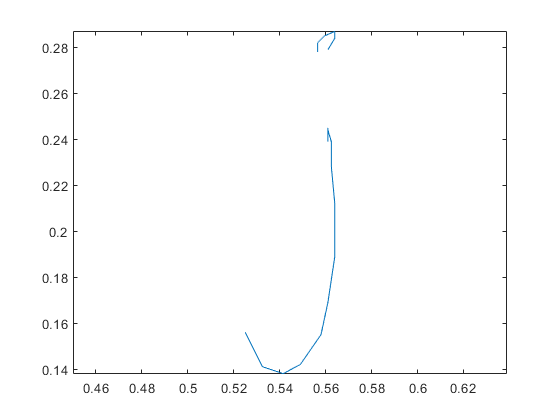

plot(letter2.X,letter2.Y)
axis equal

dur2 = letter2.Time(end)

dur2 = 0.4020

aratio2 = range(letter2.Y)/range(letter2.X)

aratio2 = 3.8205


letter3 = readtable("user001_V_1.txt");
letter3.X = letter3.X*1.5;
letter3.Time = (letter3.Time - letter3.Time(1))/1000

letter3 = 20×4 table
    Time       X         Y        P  
    _____    ______    _____    _____

        0       0.3    0.226    0.011
    0.006       0.3    0.227    0.081
    0.006       0.3    0.227    0.081
    0.024       0.3    0.229    0.382
    0.041    0.2985    0.229    0.522
    0.056       0.3    0.227    0.685
    0.073    0.3015    0.219    0.819
     0.09    0.3045    0.205    0.966
    0.108     0.309    0.185        1
    0.123     0.312    0.173        1
     0.14    0.3165    0.159        1
    0.157    0.3195    0.152        1
    0.175     0.324    0.154        1
    0.189    0.3285    0.164        1
    0.206     0.333    0.179        1
    0.223     0.339    0.201        1


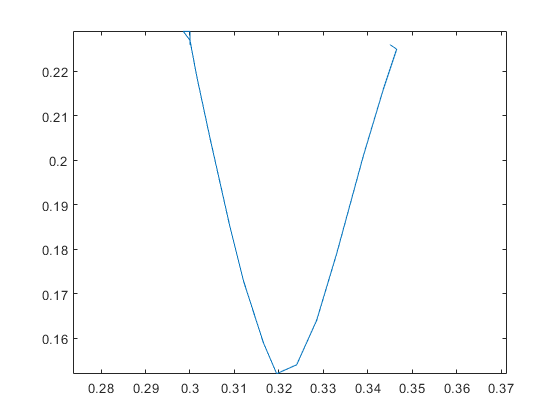

plot(letter3.X,letter3.Y)
axis equal

dur3 = letter3.Time(end)

dur3 = 0.2760

aratio3 = range(letter3.Y)/range(letter3.X)

aratio3 = 1.6042